# Multiple dynamic obstacles


--- Wave Glider Parameters ---
Average Speed: 0.59 m/s
Turning Radius: 1.50 m
Max Turn Rate: 0.393 rad/s (22.5 deg/s)

--- Initial Obstacle Positions ---
Obstacle 1: Initial position (2.0, 12.0), Motion type 1
Obstacle 2: Initial position (11.0, 7.0), Motion type 2
Obstacle 3: Initial position (6.0, 3.0), Motion type 4
Obstacle 4: Initial position (15.0, 13.0), Motion type 3

Starting wave glider path planning with dynamic obstacles...
Goal reached in 539 iterations (53.9 seconds) with dynamic obstacles!

Wave Glider Path Stats (Dynamic Environment):
  Path length: 27.20 m
  Total time: 53.9 s
  Average ground speed: 0.50 m/s
  Waypoints: 540
  Total turning: 9.39 rad (537.8 deg)


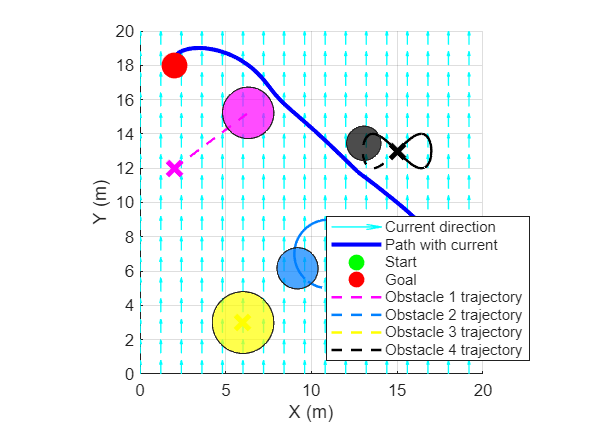

function apf_path_planning_wave_glider_dynamic()
    % Artificial Potential Field Method for Local Path Planning
    % With Wave Glider Dynamics and Dynamic Obstacles
    % Multiple dynamic obstalces

    % Clear workspace
    clear; close all; clc;

    % Environment setup
    field_size = 20;      % Size of the field
    resolution = 0.2;     % Grid resolution
    x = 0:resolution:field_size;
    y = 0:resolution:field_size;
    [X, Y] = meshgrid(x, y);

    % Robot parameters
    start_pos   = [18, 2];       % Starting position
    goal_pos    = [2, 18];     % Goal position
    robot_radius = 1.53;         % Robot radius for collision detection

    % WAVE GLIDER DYNAMICS PARAMETERS
    wave_glider.avg_speed = 0.59;        % Average speed (m/s)
    wave_glider.turning_radius = 1.5;   % Minimum turning radius (m)
    wave_glider.max_turn_rate = wave_glider.avg_speed / wave_glider.turning_radius; % rad/s

    % DYNAMIC OBSTACLES SETUP
    % Each obstacle: [x_initial, y_initial, radius, vx, vy, motion_type, param1, param2, param3, param4]
    % Motion types: 1=linear, 2=circular, 3=figure-8, 4=stationary
    % 
    % For CIRCULAR motion: param1=radius_from_center, param2=angular_vel, param3=phase_offset, param4=unused
    %   The obstacle will orbit around (x_initial, y_initial) at distance param1
    % For FIGURE-8 motion: param1=size_param, param2=angular_vel, param3=phase_offset, param4=unused  
    %   The obstacle will move in figure-8 pattern centered at (x_initial, y_initial)
    
    dynamic_obstacles = [
        % [x, y, radius, vx, vy, motion_type, param1, param2, param3, param4]
        2, 12, 1.5, 0.08, 0.06, 1, 0, 0, 0, 0;          % Linear motion
        11, 7, 1.2, 0, 0, 2, 2, 0.3, 0, 0;          % Circular
        6, 3, 1.8, 0, 0, 4, 0, 0, 0, 0;               % Stationary
        15, 13, 1, 0, 0, 3, 2, 0.2, 0, 0;         % Figure-8
    ];

    % APF parameters
    k_att = 1;        % Attractive force gain
    k_rep = 15;       % Repulsive force gain for dynamic obstacles
    d0    = 4;        % Influence distance
    dt    = 0.1;        % Time step for wave glider dynamics (s)
    max_iterations = 3000; % Increased for dynamic environment

    % Current (environment) parameters
    U_current = 0.2;        % Current speed (m/s)
    theta_rad = pi/2;          % Direction (0 rad = to the right/east)
    k_env     = 2;        % Weight of environmental influence

    % Current vector (constant everywhere)
    [Ux, Uy, phi_current] = uniform_current_field(X, Y, U_current, theta_rad);

    % Display wave glider parameters
    fprintf('\n--- Wave Glider Parameters ---\n');
    fprintf('Average Speed: %.2f m/s\n', wave_glider.avg_speed);
    fprintf('Turning Radius: %.2f m\n', wave_glider.turning_radius);
    fprintf('Max Turn Rate: %.3f rad/s (%.1f deg/s)\n', wave_glider.max_turn_rate, rad2deg(wave_glider.max_turn_rate));

    % Display obstacle initial positions
    fprintf('\n--- Initial Obstacle Positions ---\n');
    for i = 1:size(dynamic_obstacles, 1)
        fprintf('Obstacle %d: Initial position (%.1f, %.1f), Motion type %d\n', ...
            i, dynamic_obstacles(i,1), dynamic_obstacles(i,2), dynamic_obstacles(i,6));
    end

    % Path planning with dynamic obstacles
    [path_with_dynamics, obstacle_history] = path_planning_wave_glider_dynamic(start_pos, goal_pos, dynamic_obstacles, ...
        k_att, k_rep, d0, dt, max_iterations, robot_radius, k_env, Ux, Uy, wave_glider);

    % Visualization
    visualize_dynamic_results(X, Y, start_pos, goal_pos, dynamic_obstacles, ...
        path_with_dynamics, obstacle_history, field_size, Ux, Uy, wave_glider);
end

%% Dynamic Wave Glider Path Planning 
function [path, obstacle_history] = path_planning_wave_glider_dynamic(start_pos, goal_pos, dynamic_obstacles, ...
    k_att, k_rep, d0, dt, max_iter, robot_radius, k_env, Ux, Uy, wave_glider)

    % Initialize state
    current_pos = start_pos;
    current_heading = 0; % Initial heading (rad)
    current_speed = wave_glider.avg_speed; % Constant speed
    current_time = 0;
    
    path = current_pos;
    headings = current_heading;
    obstacle_history = {}; % Store obstacle positions over time
    goal_threshold = 0.2;

    % Constant current vector at any (x,y)
    c = [Ux(1,1), Uy(1,1)];

    fprintf('\nStarting wave glider path planning with dynamic obstacles...\n');
    
    for iter = 1:max_iter
        % Update obstacle positions based on their motion models
        current_obstacles = update_obstacle_positions(dynamic_obstacles, current_time);
        obstacle_history{end+1} = current_obstacles; %#ok<AGROW>
        
        % Calculate desired direction from APF forces (using current obstacle positions)
        [F_x, F_y] = calculate_forces_dynamic(current_pos, goal_pos, current_obstacles, ...
            k_att, k_rep, d0, k_env, c);

        % Desired heading from forces
        desired_heading = atan2(F_y, F_x);
        
        % Calculate heading error and apply turning radius constraint
        heading_error = angle_diff(desired_heading, current_heading);
        
        % Limit turn rate based on turning radius
        max_heading_change = wave_glider.max_turn_rate * dt;
        
        if abs(heading_error) > max_heading_change
            % Can't turn fast enough - limit the turn
            heading_change = sign(heading_error) * max_heading_change;
            current_heading = current_heading + heading_change;
        else
            % Can achieve desired heading
            current_heading = desired_heading;
        end
        
        % Normalize heading to [-pi, pi]
        current_heading = atan2(sin(current_heading), cos(current_heading));
        
        % Calculate velocity vector (including current effect)
        vx_body = current_speed * cos(current_heading);
        vy_body = current_speed * sin(current_heading);
        
        % Add current effect
        vx_ground = vx_body + c(1);
        vy_ground = vy_body + c(2);
        
        % Update position
        next_pos = current_pos + dt * [vx_ground, vy_ground];

        % Collision check with current obstacle positions
        collision = false;
        for i = 1:size(current_obstacles, 1)
            oc = current_obstacles(i, 1:2); orad = current_obstacles(i, 3);
            if norm(next_pos - oc) < (orad + robot_radius)
                collision = true; 
                break;
            end
        end

        if ~collision
            current_pos = next_pos;
            path = [path; current_pos]; %#ok<AGROW>
            headings = [headings; current_heading]; %#ok<AGROW>
            current_time = current_time + dt;
        else
            
            % Try turning left or right to avoid collision
            avoidance_successful = false;
            for turn_sign = [-1, 1] % Try left turn first, then right
                test_heading = current_heading + turn_sign * max_heading_change * 1;
                test_vx = current_speed * cos(test_heading) + c(1);
                test_vy = current_speed * sin(test_heading) + c(2);
                test_pos = current_pos + dt * [test_vx, test_vy];
                
                % Check if this avoids collision
                test_collision = false;
                for i = 1:size(current_obstacles, 1)
                    oc = current_obstacles(i, 1:2); orad = current_obstacles(i, 3);
                    if norm(test_pos - oc) < (orad + robot_radius)
                        test_collision = true;
                        break;
                    end
                end
                
                if ~test_collision
                    current_heading = test_heading;
                    current_pos = test_pos;
                    path = [path; current_pos]; %#ok<AGROW>
                    headings = [headings; current_heading]; %#ok<AGROW>
                    current_time = current_time + dt;
                    avoidance_successful = true;
                    break;
                end
            end
            
            % If still collision, just advance time and stay in place
            if ~avoidance_successful
                current_time = current_time + dt;
                path = [path; current_pos]; %#ok<AGROW>
                headings = [headings; current_heading]; %#ok<AGROW>
            end
        end

        % Goal check
        if norm(current_pos - goal_pos) < goal_threshold
            fprintf('Goal reached in %d iterations (%.1f seconds) with dynamic obstacles!\n', iter, current_time);
            break;
        end

    end

    if iter == max_iter
        fprintf('Maximum iterations reached. Final distance to goal: %.2f m\n', norm(current_pos - goal_pos));
    end

    % Path statistics
    if size(path, 1) > 1
        path_length = sum(vecnorm(diff(path), 2, 2));
        total_time = current_time;
        avg_ground_speed = path_length / total_time;
        
        fprintf('\nWave Glider Path Stats (Dynamic Environment):\n');
        fprintf('  Path length: %.2f m\n', path_length);
        fprintf('  Total time: %.1f s\n', total_time);
        fprintf('  Average ground speed: %.2f m/s\n', avg_ground_speed);
        fprintf('  Waypoints: %d\n', size(path,1));
        
        % Calculate turning statistics
        if length(headings) > 1
            heading_changes = diff(headings);
            heading_changes = atan2(sin(heading_changes), cos(heading_changes));
            total_turning = sum(abs(heading_changes));
            fprintf('  Total turning: %.2f rad (%.1f deg)\n', total_turning, rad2deg(total_turning));
        end
    end
end

%% Dynamic Obstacle Update Function 
function current_obstacles = update_obstacle_positions(dynamic_obstacles, t)
    current_obstacles = zeros(size(dynamic_obstacles, 1), 3); % [x, y, radius]
    
    for i = 1:size(dynamic_obstacles, 1)
        x0 = dynamic_obstacles(i, 1);        % Initial/center x position
        y0 = dynamic_obstacles(i, 2);        % Initial/center y position
        radius = dynamic_obstacles(i, 3);    % Obstacle radius
        vx = dynamic_obstacles(i, 4);        % Velocity x (for linear motion)
        vy = dynamic_obstacles(i, 5);        % Velocity y (for linear motion)
        motion_type = dynamic_obstacles(i, 6);
        
        switch motion_type
            case 1 % Linear motion - starts from (x0, y0)
                x = x0 + vx * t;
                y = y0 + vy * t;
                
            case 2 % Circular motion - orbits around (x0, y0)
                orbit_radius = dynamic_obstacles(i, 7);    % Distance from center
                angular_vel = dynamic_obstacles(i, 8);     % Angular velocity
                phase_offset = dynamic_obstacles(i, 9);    % Phase offset
                
                angle = angular_vel * t + phase_offset;
                x = x0 + orbit_radius * cos(angle);        % Center at (x0, y0)
                y = y0 + orbit_radius * sin(angle);
                
            case 3 % Figure-8 motion - centered at (x0, y0)
                size_param = dynamic_obstacles(i, 7);      % Size of figure-8
                angular_vel = dynamic_obstacles(i, 8);     % Angular velocity
                phase_offset = dynamic_obstacles(i, 9);    % Phase offset
                
                angle = angular_vel * t + phase_offset;
                x = x0 + size_param * sin(angle);          % Center at (x0, y0)
                y = y0 + size_param * sin(2 * angle) / 2;
                
            case 4 % Stationary - stays at (x0, y0)
                x = x0;
                y = y0;
                
            otherwise
                x = x0;
                y = y0;
        end
        
        current_obstacles(i, :) = [x, y, radius];
    end
end

%% Modified Force Calculation for Dynamic Obstacles 
function [F_x, F_y] = calculate_forces_dynamic(pos, goal, obstacles, k_att, k_rep, d0, k_env, c)
    % Attractive force
    x = pos(1); y = pos(2);
    F_att_x = -k_att * (x - goal(1));
    F_att_y = -k_att * (y - goal(2));

    % Repulsive forces from current obstacle positions
    F_rep_x = 0; F_rep_y = 0;
    for i = 1:size(obstacles, 1)
        ox = obstacles(i, 1); oy = obstacles(i, 2); orad = obstacles(i, 3);
        d_center = sqrt((x - ox)^2 + (y - oy)^2);
        d_obs = d_center - orad;

        if d_obs > 0 && d_obs <= d0
            % Unit vector from obstacle center to robot
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);

            F_rep_mag = k_rep * (1/d_obs - 1/d0) * (1/d_obs^2);
            F_rep_x = F_rep_x + F_rep_mag * ux;
            F_rep_y = F_rep_y + F_rep_mag * uy;

        elseif d_obs <= 0
            % Strong repulsion if inside obstacle
            ux = (x - ox) / max(d_center, eps);
            uy = (y - oy) / max(d_center, eps);
            F_rep_x = F_rep_x + 200 * ux; % Increased for dynamic obstacles
            F_rep_y = F_rep_y + 200 * uy;
        end
    end

    % Environmental (current) force
    F_env_x = k_env * c(1);
    F_env_y = k_env * c(2);

    % Total force
    F_x = F_att_x + F_rep_x + F_env_x;
    F_y = F_att_y + F_rep_y + F_env_y;
end

%% Helper Functions
function diff = angle_diff(angle1, angle2)
    diff = angle1 - angle2;
    diff = atan2(sin(diff), cos(diff));
end

function [Ux, Uy, phi] = uniform_current_field(X, Y, U, theta_rad)
    cx = cos(theta_rad); sy = sin(theta_rad);
    Ux = U * cx * ones(size(X));
    Uy = U * sy * ones(size(Y));
    phi = U * (cx .* X + sy .* Y);
end

%% Visualization for Dynamic Results
function visualize_dynamic_results(X, Y, start_pos, goal_pos, dynamic_obstacles, ...
    path_with_dynamics, obstacle_history, field_size, Ux, Uy, wave_glider)

    figure('Position', [100, 100, 1000, 700]);
    
    % Create animated plot
    hold on;
    
    % Plot current field (simplified)
    skip = 6;
    X_sub = X(1:skip:end, 1:skip:end);
    Y_sub = Y(1:skip:end, 1:skip:end);
    Ux_sub = Ux(1:skip:end, 1:skip:end);
    Uy_sub = Uy(1:skip:end, 1:skip:end);
    quiver(X_sub, Y_sub, Ux_sub*5, Uy_sub*5, 0.5, 'Color', [0, 1, 1, 0.4], 'LineWidth', 0.8, 'DisplayName', 'Current direction');
    
    % Plot complete wave glider path
    plot(path_with_dynamics(:,1), path_with_dynamics(:,2), 'b-', 'LineWidth', 2.5, 'DisplayName', 'Path with current');
    
    % Start and goal points
    plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 15, 'MarkerFaceColor','g', 'DisplayName','Start');
    plot(goal_pos(1),  goal_pos(2),  'ro', 'MarkerSize', 15, 'MarkerFaceColor','r', 'DisplayName','Goal');
    
    % Show obstacle trajectories
    colors = {'m', [0, 0.5, 1], 'y', 'k'};
    for i = 1:size(dynamic_obstacles, 1)
        obstacle_traj = zeros(length(obstacle_history), 2);
        for t = 1:length(obstacle_history)
            if size(obstacle_history{t}, 1) >= i
                obstacle_traj(t, :) = obstacle_history{t}(i, 1:2);
            end
        end
        if i <= length(colors)
            color = colors{i};
        else
            color = colors{mod(i-1, length(colors)) + 1};
        end
        plot(obstacle_traj(:,1), obstacle_traj(:,2), '--', 'Color', color, 'LineWidth', 1.5, ...
             'DisplayName', sprintf('Obstacle %d trajectory', i));
    end
    
    % Show initial obstacle positions with 'X' markers (where they actually start moving from)
    for i = 1:size(dynamic_obstacles, 1)
        if i <= length(colors)
            color = colors{i};
        else
            color = colors{mod(i-1, length(colors)) + 1};
        end
        
        % Calculate the actual starting position based on motion type
        motion_type = dynamic_obstacles(i, 6);
        if motion_type == 2 % Circular motion
            % For circular motion, start position is on the radius at t=0
            center_x = dynamic_obstacles(i, 1);
            center_y = dynamic_obstacles(i, 2);
            orbit_radius = dynamic_obstacles(i, 7);
            phase_offset = dynamic_obstacles(i, 9);
            
            start_x = center_x + orbit_radius * cos(phase_offset);
            start_y = center_y + orbit_radius * sin(phase_offset);
            plot(start_x, start_y, 'x', 'Color', color, 'MarkerSize', 12, 'LineWidth', 3, 'HandleVisibility', 'off');
        else
            % For all other motion types, use the initial position directly
            plot(dynamic_obstacles(i,1), dynamic_obstacles(i,2), 'x', 'Color', color, 'MarkerSize', 12, 'LineWidth', 3, 'HandleVisibility', 'off');
        end
    end
    
    % Show final obstacle positions
    if ~isempty(obstacle_history)
        final_obstacles = obstacle_history{end};
        for i = 1:size(final_obstacles, 1)
            cx = final_obstacles(i,1); cy = final_obstacles(i,2); cr = final_obstacles(i,3);
            th = linspace(0, 2*pi, 100);
            xf = cx + cr*cos(th); yf = cy + cr*sin(th);
            if i <= length(colors)
                fill_color = colors{i};
            else
                fill_color = colors{mod(i-1, length(colors)) + 1};
            end
            fill(xf, yf, fill_color, 'FaceAlpha', 0.7, 'HandleVisibility', 'off');
        end
    end
   
    xlabel('X (m)'); ylabel('Y (m)');
    legend('show', 'Location', 'best');
    axis equal; xlim([0, field_size]); ylim([0, field_size]); grid on;
    
    % Add text with motion information
    motion_info = {};
    for i = 1:size(dynamic_obstacles, 1)
        switch dynamic_obstacles(i, 6)
            case 1
                motion_info{i} = sprintf('Obs %d: Linear from (%.1f,%.1f), v=(%.1f,%.1f)', ...
                    i, dynamic_obstacles(i, 1), dynamic_obstacles(i, 2), dynamic_obstacles(i, 4), dynamic_obstacles(i, 5));
            case 2
                motion_info{i} = sprintf('Obs %d: Circular around (%.1f,%.1f), R=%.1f, ω=%.2f', ...
                    i, dynamic_obstacles(i, 1), dynamic_obstacles(i, 2), dynamic_obstacles(i, 7), dynamic_obstacles(i, 8));
            case 3
                motion_info{i} = sprintf('Obs %d: Figure-8 at (%.1f,%.1f), size=%.1f, ω=%.2f', ...
                    i, dynamic_obstacles(i, 1), dynamic_obstacles(i, 2), dynamic_obstacles(i, 7), dynamic_obstacles(i, 8));
            case 4
                motion_info{i} = sprintf('Obs %d: Stationary at (%.1f,%.1f)', ...
                    i, dynamic_obstacles(i, 1), dynamic_obstacles(i, 2));
        end
    end
end

% Run the simulation
apf_path_planning_wave_glider_dynamic();